% --- EJEMPLO CLASE 4 MEJORADO CON VALIDACIÓN CRUZADA Y MATRIZ FINAL ---
% Author: Prof. Aboud BARSEKH ONJI (D.Sc.)
% Este script implementa una evaluación robusta usando K-Fold Cross-Validation
% y muestra una matriz de confusión agregada con los resultados de todas las rondas.

clear; clc; close all;

%% PASO 1: CARGAR LOS DATOS
fprintf('Paso 1: Cargando los datos...\n');

Paso 1: Cargando los datos...


data = readtable('factoryreport.csv');
textos = data.Description;
categorias = categorical(data.Category);

%% PASO 2: CONFIGURAR LA VALIDACIÓN CRUZADA (K-FOLD)
fprintf('Paso 2: Configurando la Validación Cruzada (5-Folds)...\n\n');

Paso 2: Configurando la Validación Cruzada (5-Folds)...



k = 5;
cvp = cvpartition(categorias, 'KFold', k);

% --- NUEVO: Arrays para guardar los resultados de TODOS los folds ---
all_predictions = categorical([]); % Para guardar todas las predicciones
all_true_labels = categorical([]);   % Para guardar todas las etiquetas reales

accuracies = zeros(k, 1);

%% BUCLE DE ENTRENAMIENTO Y EVALUACIÓN
for i = 1:k
    fprintf('--- Procesando Fold %d/%d ---\n', i, k);
    
    % Dividir los datos para este fold
    idxEntrenamiento = training(cvp, i);
    idxPrueba = test(cvp, i);
    
    textosEntrenamiento = textos(idxEntrenamiento);
    categoriasEntrenamiento = categorias(idxEntrenamiento);
    textosPrueba = textos(idxPrueba);
    categoriasPrueba = categorias(idxPrueba);

    % Preprocesar y Vectorizar
    documentosEntrenamiento = tokenizedDocument(lower(textosEntrenamiento));
    documentosEntrenamiento = erasePunctuation(documentosEntrenamiento);
    documentosEntrenamiento = removeStopWords(documentosEntrenamiento);
    documentosEntrenamiento = normalizeWords(documentosEntrenamiento, 'Style', 'stem');
    
    bolsa = bagOfWords(documentosEntrenamiento);
    matrizEntrenamiento = tfidf(bolsa);

    % Entrenar el Modelo
    modeloClasificador = fitcecoc(matrizEntrenamiento, categoriasEntrenamiento);

    % Probar el Modelo
    documentosPrueba = tokenizedDocument(lower(textosPrueba));
    documentosPrueba = erasePunctuation(documentosPrueba);
    documentosPrueba = removeStopWords(documentosPrueba);
    documentosPrueba = normalizeWords(documentosPrueba, 'Style', 'stem');
    
    matrizPrueba = tfidf(bolsa, documentosPrueba);
    predicciones = predict(modeloClasificador, matrizPrueba);

    % Evaluar y guardar la exactitud de este fold
    exactitud_fold = sum(predicciones == categoriasPrueba) / numel(categoriasPrueba);
    accuracies(i) = exactitud_fold;
    fprintf('Exactitud en este Fold: %.2f%%\n\n', exactitud_fold * 100);
    
    % --- NUEVO: Guardar los resultados de esta ronda para la matriz final ---
    all_predictions = [all_predictions; predicciones];
    all_true_labels = [all_true_labels; categoriasPrueba];
end

--- Procesando Fold 1/5 ---


Exactitud en este Fold: 25.00%



--- Procesando Fold 2/5 ---


Exactitud en este Fold: 20.00%



--- Procesando Fold 3/5 ---


Exactitud en este Fold: 20.00%



--- Procesando Fold 4/5 ---


Exactitud en este Fold: 25.00%



--- Procesando Fold 5/5 ---


Exactitud en este Fold: 25.00%




%% RESULTADOS FINALES
fprintf('--- Evaluación Final Completada ---\n');

--- Evaluación Final Completada ---


mean_accuracy = mean(accuracies);
std_accuracy = std(accuracies);

fprintf('La exactitud promedio del modelo es: %.2f%%\n', mean_accuracy * 100);

La exactitud promedio del modelo es: 23.00%


fprintf('La desviación estándar de la exactitud fue: %.2f%%\n', std_accuracy * 100);

La desviación estándar de la exactitud fue: 2.74%



% --- NUEVO: Dibujar la matriz de confusión con los resultados agregados ---
fprintf('Mostrando la matriz de confusión agregada de todos los folds...\n');

Mostrando la matriz de confusión agregada de todos los folds...


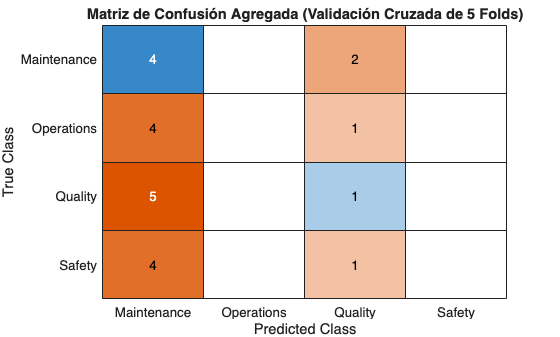

figure;
confusionchart(all_true_labels, all_predictions);
title('Matriz de Confusión Agregada (Validación Cruzada de 5 Folds)');